分回合展示事件记录

## 语法

## 示例

## 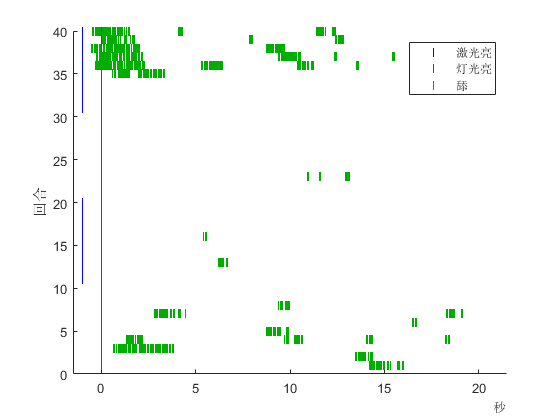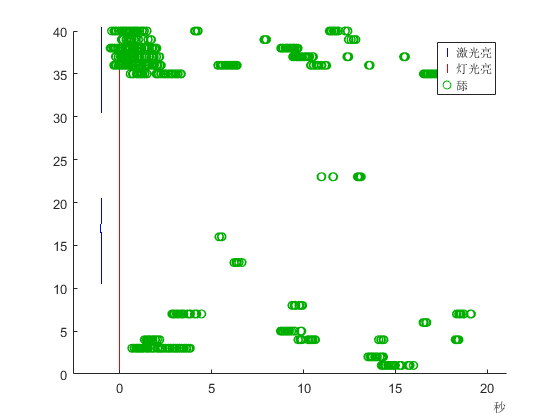

## 输入参数

EventLog tabular，事件记录表，至少包含以下列：

- Time(:,1)duration，从会话开始经历的时间

- Event(:,1)categorical，事件

TrialMarker(1,:)categorical，用于分割回合的标志性事件。如果指定多个，则每个事件都视为单独的回合。

TrialRange(1,2)duration，二元素向量分别表示回合开始和结束相对于TrialMarker的时间。例如seconds([-6,20])表示回合开始于TrialMarker前6秒，到后20秒为止。

### 名称值参数

ExcludedEvents(1,:)categorical=categorical.empty(1,0)，排除的事件，不会在图上显示出来

ExcludedTrials(1,:)=zeros(1,0)，排除的回合序数。这些回合在图上表现为空行，但仍占用空间。

EventStyle table，为每种事件指定特定的scatter样式，使用行名称指定事件名称。每一列的名称将作为名称值参数的名称提供给scatter函数，参数值取对应事件所在行。例如，Marker列指定形状，MarkerEdgeColor指定形状颜色等。如果不指定，Marker默认为'|'，MarkerEdgeColor自动分配。未在TrialRagne确定的回合范围中的事件不参与自动分配。

## 返回值

LegendTable(:,2)table，图例表，每行一个事件类型，包含以下列：

- Scatter(:,1)matlab.graphics.chart.primitive.Scatter，该事件类型对应的散点

- Event(:,1)categorical，事件类型名称

如果获取返回值，此函数将不会自动添加图例。如果不获取返回值，此函数将会自动添加图例。如果某类事件从未出现在TrialRange确定的回合范围中，那个事件也不会出现在图例中。

function LegendTable=TrialwiseEventPlot(EventLog,TrialMarker,TrialRange,options)
arguments
	EventLog
	TrialMarker categorical
	TrialRange
	options.ExcludedEvents categorical=categorical.empty(1,0)
	options.ExcludedTrials(1,:)=zeros(1,0)
	options.EventStyle
end
if ~isduration(TrialRange)
	TrialRange=seconds(TrialRange);
end
TrialEventIndices=find(ismember(EventLog.Event,TrialMarker));
EventLog.TrialIndex(:)=0x0;
for T=1:numel(TrialEventIndices)
	TrialTime=EventLog.Time(TrialEventIndices(T));
	ThisTrialRange=TrialTime+TrialRange;
	Logical=EventLog.Time>ThisTrialRange(1)&EventLog.Time<ThisTrialRange(2);
	EventLog.TrialIndex(Logical)=T;
	EventLog.TrialTime(Logical)=EventLog.Time(Logical)-TrialTime;
end
EventLog(ismember(EventLog.TrialIndex,[0,options.ExcludedTrials]),:)=[];
EventLog(ismember(EventLog.Event,options.ExcludedEvents),:)=[];
[Group,Event]=findgroups(string(EventLog.Event));
NumColors=numel(Event);
Colors=GlobalOptimization.ColorAllocate(NumColors,[1,1,1;1,1,1]);
Scatter=gobjects(NumColors,1);
HasEventStyle=isfield(options,'EventStyle');
if HasEventStyle
	RequireStyles=~ismember(["Marker","MarkerEdgeColor"],options.EventStyle.Properties.VariableNames);
end
for G=1:NumColors
	EL=EventLog(Group==G,:);
	if HasEventStyle
		[~,Index]=ismember(Event(G),options.EventStyle.Properties.RowNames);
		if Index
			Style=[options.EventStyle.Properties.VariableNames;table2cell(options.EventStyle(Index,:))];
			if RequireStyles(1)
				Style=[{'|'};Style(:)];
			end
			if RequireStyles(2)
				Style=[Style(:);{'MarkerEdgeColor';Colors(G,:)}];
			end
		else
			Style={'|','MarkerEdgeColor',Colors(G,:)};
		end
	else
		Style={'|','MarkerEdgeColor',Colors(G,:)};
	end
	Scatter(G)=scatter(EL.TrialTime,EL.TrialIndex,Style{:});
	hold on;
end
if nargout
	LegendTable=table(Scatter,Event);
else
	legend(Scatter,Event);
end
xlim(xlim+seconds([-1,1]));